# Map Estimation

## 1. Load data

clear all; 
load('../1-Cleaning/data/dc_corr.mat'); 
load('../1-Cleaning/data/sunrisesunset_grid.mat')
load('../1-Cleaning/data/Rain_grid.mat','TCRW');
load('../2-Inference/data/Density_inference.mat'); 
addpath('./functions/'); 
load coastlines.mat

## 2. Initialization of the grid

g.lat=43:.2:68;
g.lon=-5:.2:30;
g.time = (start_date:1/24/4:end_date);
g.atime=unique(round(datenum(g.time)));

g.nlat=numel(g.lat);
g.nlon=numel(g.lon);
g.nl=numel(g.lat)*numel(g.lon);
g.nt=numel(g.time);
g.nat=numel(g.atime);

[g.lat3D,g.lon3D,g.time3D]=ndgrid(g.lat,g.lon,g.time);
[g.lat2D, g.lon2D] = ndgrid(g.lat,g.lon);

ndc = numel(dc);
dclat = [dc.lat]';
dclon = [dc.lon]';

## 3. Mask

Mask water

g.mask_water = inpolygon(g.lat2D,g.lon2D,coastlat,coastlon);

Mask distance Radar

Ddist = pdist2([dclat dclon], [g.lat2D(:) g.lon2D(:)], @lldistkm);
g.mask_distrad = intrahape(min(Ddist)<250,size(g.lat2D));

Combined spatial mask s

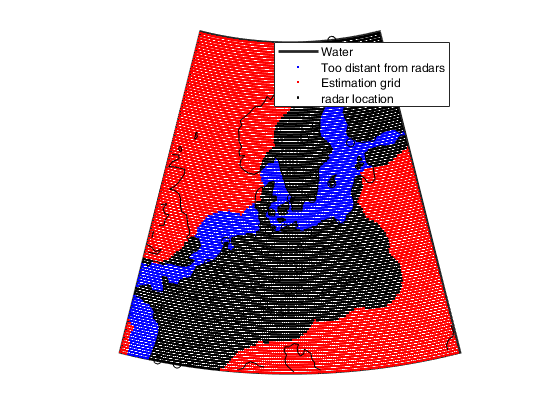

g.latlonmask = (g.mask_water &  g.mask_distrad);
g.nlm = sum(g.latlonmask(:));
figure; hold on; 
h=worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); 
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
plotm(g.lat2D(~g.mask_water),g.lon2D(~g.mask_water),'.b')
plotm(g.lat2D(~g.mask_distrad),g.lon2D(~g.mask_distrad),'.r')
plotm(g.lat2D(g.latlonmask),g.lon2D(g.latlonmask),'.k')
plotm(dclat', dclon','ok')
plotm(coastlat, coastlon,'k')
legend('Water','Too distant from radars','Estimation grid','radar location')

Sunrise and sunset

g.sunrise = nan(g.nlat,g.nlon,g.nt);
g.sunset = g.sunrise;
for i_t=1:numel(tim_d)-1
    id = g.time>tim_d(i_t) & g.time<=tim_d(i_t+1);
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_e(:,:,i_t));
    g.sunset(:,:,id)=repmat(F(g.lat2D,g.lon2D),1,1,sum(id));
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_b(:,:,i_t+1));
    g.sunrise(:,:,id)=repmat(F(g.lat2D,g.lon2D),1,1,sum(id));
end

figure('position',[0 0 1000 400]); hold on;
plot(g.time(:),intrahape(mean(mean(g.sunset,1),2),1,2017))
plot(g.time(:),intrahape(mean(mean(g.sunrise,1),2),1,2017))
legend('sunset','sunrise'); xlabel('Continous time t'); ylabel('Day of closer night'); datetick('y'); axis tight

Normalized night time (NNT)

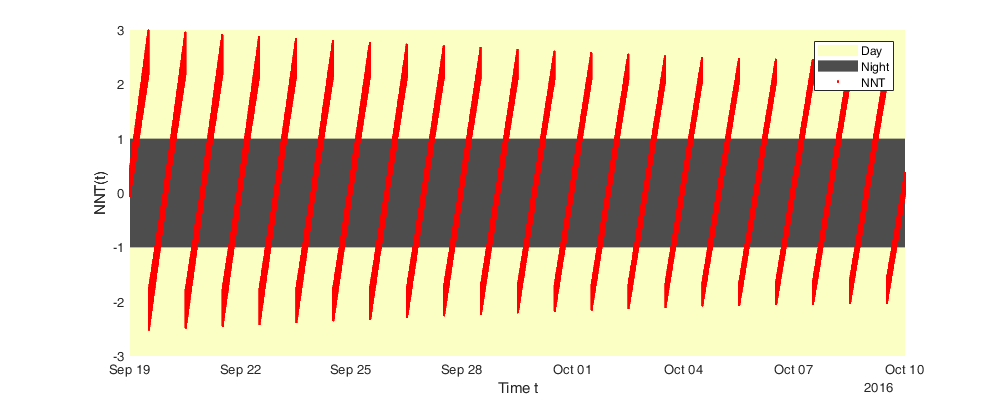

g.NNT = (datenum(g.time3D)-mean(cat(4,g.sunrise,g.sunset),4)) ./ (g.sunrise-g.sunset)*2;
figure('position',[0 0 1000 400]); hold on
fill([g.time(1) g.time(end) g.time(end) g.time(1)],[-3 -3 3 3],[252, 255, 196]./255,'EdgeColor','none')
fill([g.time(1) g.time(end) g.time(end) g.time(1)],[-1 -1 1 1],[.3 .3 .3],'EdgeColor','none')
plot(g.time3D(:), g.NNT(:), '.r' ); 
xlabel('Time t'); ylabel('NNT(t)');
legend('Day','Night','NNT');

Mask of the day

g.mask_day =  g.NNT>-1 & g.NNT<1;

Group g.time by night

[~,g.dateradar] = ismember(round(intrahape(g.sunrise(1,1,:),g.nt,1)),g.atime);

Mask Rain

We calibrate the threashold value of rain rate at which bird density is affected 

% rain = [];
% for i_d=1:ndc
%     id=dc(i_d).NNT<1&dc(i_d).NNT>-1;
%     rain=[rain; repmat(i_d,sum(id),1) dc(i_d).denss(id), dc(i_d).tcrw(id) nansum(dc(i_d).DBZH(id,:),2)];
% end
% figure;
% subplot(3,1,1);scatter(rain(:,2),rain(:,4),'.'); xlabel('density');ylabel('DBZH')
% subplot(3,1,2);scatter(rain(:,2),rain(:,3),'.');xlabel('density');ylabel('tcrw')
% subplot(3,1,3);scatter(rain(:,3),rain(:,4),'.');xlabel('tcrw');ylabel('DBZH')
% 
% figure; hold on; plot(rain(:,2)); yyaxis right; plot(rain(:,3))
% 
% % histogram of rain
% histogram(log10(rain(:,3)))
% 
% histogram(log10(rain(:,2)))
% 
% % Compare histogram of rain vs no rain
% id=rain(:,3)<10^-8;
% figure; hold on;
% histogram((rain(id,2)))
% histogram((rain(~id,2)))
% legend('no Rain','Rain')
% 
% VAL=0:0.001:0.1;
% r=nan(size(VAL));
% r2=nan(size(VAL));
% r3=nan(size(VAL));
% for i_val=1:numel(VAL)
%     id=rain(:,3)>VAL(i_val);
%     r(i_val)=mean(rain(id,2)==0);
%     r2(i_val)=mean(rain(~id,2)==0);
%     r3(i_val)=sum(id);
% end
% figure; hold on; plot(VAL,r);plot(VAL,r2); 
%  yyaxis right; plot(VAL,r3); 
% xlabel('threashold'); ylabel('percent of 0 value');
% legend('in removed data','in kept data')


This threashold value is determine to 0.03 (0.02-0.05)

g.mask_rain_thr=0.03;
g.mask_rain=TCRW<g.mask_rain_thr;

Clear the masking variable

clear sunrs_b sunrs_e lat_d lon_d F tim_d dc

## 4. Multi-night scale

Covariance matrix of weather radars

Dtime=squareform(pdist(multi.T(~multi.isnan)));
Ddist=squareform(pdist([dclat(multi.R(~multi.isnan)) dclon(multi.R(~multi.isnan))],@lldistkm));
Caa = multi.cov.C(Ddist,Dtime);

 Cross-covariance of the radar data

Ddist = pdist2([dclat dclon], [g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)], @lldistkm);
Ddist_sf = Ddist(multi.R(~multi.isnan),repmat((1:g.nlm)',g.nat,1));
Dtime_sf = pdist2(multi.T(~multi.isnan), repelem(g.atime',g.nlm,1));

Cab = multi.cov.C(Ddist_sf,Dtime_sf);

Compute the Kriging Weight

Lambda = inv(Caa)*Cab;

Kriging estimation

gmulti.M_est = nan(g.nlat,g.nlon,g.nat);
gmulti.M_est(repmat(g.latlonmask,1,1,g.nat)) = (Lambda' * multi.Mn) + repmat(g.lat2D(g.latlonmask),g.nat,1)*multi.w(2)+multi.w(1);

Kriging Variance

gmulti.M_sig = nan(g.nlat,g.nlon,g.nat);
gmulti.M_sig(repmat(g.latlonmask,1,1,g.nat)) = sqrt(sum(multi.cov.parm(1:3)) - sum(Lambda.*Cab));

Figure

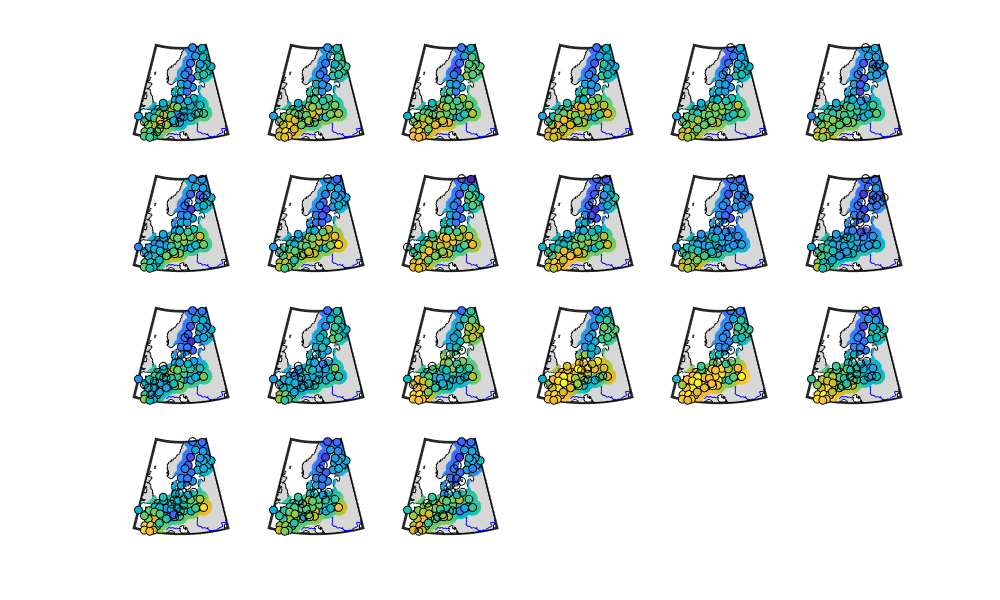

figure('position',[0 0 1000 600]); 
for i_t = 1:g.nat-1
    subplot(4,6,i_t); hold on; 
    h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
    surfm(g.lat2D,g.lon2D,gmulti.M_est(:,:,i_t)); caxis([.6 1.9])
    scatterm(dclat,dclon,100,multi.M(:,i_t),'filled','MarkerEdgeColor','k')
end

Export as gif

% filename='data/Density_estimationMap_M';
filename='data/Density_estimationMap_Mn';
Frame(numel(g.atime)-1) = struct('cdata',[],'colormap',[]); 
fig=figure(2); 
h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
set(gcf,'color','w'); hsurf=[];hscat=[];
caxis([-.5 .5]); 
%caxis([0 80]);  c=colorbar;c.Label.String = 'Bird density [bird/km^2]';c.Label.FontSize=14;
for i_t = 1:numel(g.atime)-1
    delete(hsurf); delete(hscat)
    
    hsurf=surfm(g.lat2D,g.lon2D,gmulti.M_est(:,:,i_t)-g.lat2D*multi.w(2)-multi.w(1));
    hscat=scatterm(dclat,dclon,[],multi.M(:,i_t)-dclat(multi.r)*multi.w(2)-multi.w(1),'filled','MarkerEdgeColor','k');
%     hsurf=surfm(g.lat2D,g.lon2D,gmulti.M_est(:,:,i_t).^(1/pow));
%     hscat=scatterm(dclat,dclon,[],multi.M(:,i_t).^(1/pow),'filled','MarkerEdgeColor','k');
    
    title(datestr(g.atime(i_t)),'FontSize',14); drawnow;
    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 1
        imwrite(imind,cm,[filename '.gif'],'gif','Loopcount',inf);
    else
        imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append');
    end
end


## 5. Intra-night scale

Covariance matrix of weather radar data 

Dtime = squareform(pdist(data.time));
Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));
Ddist = Ddist_sm(data.radar,data.radar);
tic;Caa = intra.cov.C(Ddist,Dtime);toc

Dtime_sm = single(pdist2(data.time, datenum(g.time')));
Ddist_sm = single(pdist2([dclat dclon], [g.lat2D(:) g.lon2D(:)], @lldistkm));

gintra_In_est = nan(size(g.mask_day));
gintra_In_sig = nan(size(g.mask_day));

for i_t=1:g.nat
    mask_r = data.day==i_t;

    mask_g = g.mask_day & repmat(reshape(g.dateradar==i_t,1,1,[]),g.nlat,g.nlon,1) & repmat(g.latlonmask,1,1,g.nt);
    
    [tmp_i,tmp_j,tmp_k] = ind2sub(size(g.time3D),find(mask_g));
    
    Dtime_sf = Dtime_sm(mask_r,tmp_k);
    Ddist_sf = Ddist_sm(data.radar(mask_r), sub2ind(size(g.lat2D),tmp_i,tmp_j));
    
    tic;Cab = intra.cov.C(Ddist_sf,Dtime_sf);toc

    Lambda = inv(Caa(mask_r,mask_r))*Cab;

    gintra_In_est(mask_g) = Lambda' * intra.In(mask_r);
    gintra_In_sig(mask_g) = sqrt(sum(intra.cov.parm(1:3)) - sum(Lambda.*Cab)); 
    
end

gintra.I_est = gintra_In_est .* sqrt(polyval(flipud(intra.b),g.NNT)) + polyval(flipud(intra.a),g.NNT);
gintra.I_sig = sqrt( gintra_In_sig.^2 .* polyval(flipud(intra.b),g.NNT) );

Figure

% filename='data/Density_estimationMap_I';
filename='data/Density_estimationMap_In';
mask_fullday = find(~intrahape(all(all(isnan(gintra_In_est),1),2),g.nt,1));
Frame(numel(mask_fullday)-1) = struct('cdata',[],'colormap',[]);
fig=figure;
h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]); 
setm(h,'grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
set(gcf,'color','w'); hsurf=[];hscat=[];
caxis([-5 5]);

for i_t = 2:numel(mask_fullday)-1
    delete(hsurf); delete(hscat);
    hsurf=surfm(g.lat2D,g.lon2D,gintra_In_est(:,:,mask_fullday(i_t)));
    gtit = datenum(g.time(mask_fullday(i_t)+([-1 0 1])));
    id = find(mean(gtit(1:2))<data.time & mean(gtit(2:3))>data.time);
    if sum(id)>0
        [G,ID] = findgroups(data.radar(id));
        hscat=scatterm(dclat(ID),dclon(ID),[],splitapply(@mean,intra.In(id),G),'filled','MarkerEdgeColor','k');
    end
    title(datestr(g.time(mask_fullday(i_t))),'FontSize',14); drawnow
    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 2
        imwrite(imind,cm,[filename '.gif'],'gif', 'DelayTime',0.1,'Loopcount',inf);
    else
        imwrite(imind,cm,[filename '.gif'],'gif', 'DelayTime',0.1,'WriteMode','append');
    end
end
% v=VideoWriter([filename '.avi']);
% v.FrameRate = 4;
% v.Quality = 75;
% open(v);
% writeVideo(v, Frame);
% close(v);

## 6 Reassemble

gd.denst_est = gmulti.M_est(:,:,g.dateradar) + gintra.I_est;
gd.denst_sig = sqrt(gmulti.M_sig(:,:,g.dateradar).^2 + gintra.I_sig.^2);

if any(gd.denst_est(:)<0)
    disp(['WARNING: Remove ' num2str(sum(gd.denst_est(:)<0)) ' value(s) because <0'])
    gd.denst_est(gd.denst_est<0)=nan;
end

gd.dens_est = (gd.denst_est).^(1/pow);

tmp = gd.denst_est+norminv(.1).*gd.denst_sig;
if any(tmp(:)<0)
    disp(['WARNING: Set ' num2str(sum(tmp(:)<0)) ' value(s) to 0'])
    tmp(tmp<0)=0;
end
gd.dens_q10 = ( tmp ).^(1/pow);
gd.dens_q90 = ( gd.denst_est+norminv(.9).*gd.denst_sig ).^(1/pow);

Figure

fig=figure(2);  
filename='data/Density_estimationMap_B';
% mask_fullday = 1553:1609;
filename='data/Density_estimationMap_B';
mask_fullday = find(~intrahape(all(all(isnan(gd.dens_est),1),2),g.nt,1));
Frame(numel(mask_fullday)-1) = struct('cdata',[],'colormap',[]); 
h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]); 
setm(h,'grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
set(gcf,'color','w'); %hcoast=plotm(coastlat, coastlon,'k');
hsurf=[]; hscat=[];caxis([0 200]); c=colorbar;c.Label.String = 'Bird density [bird/km^2]';c.Label.FontSize=14;
for i_t = 2:numel(mask_fullday)
    delete(hsurf); delete(hscat);
    hsurf=surfm(g.lat2D,g.lon2D,gd.dens_est(:,:,mask_fullday(i_t)));
    gtit = datenum(g.time(mask_fullday(i_t)+([-1 0 1])));
    id = find(mean(gtit(1:2))<data.time & mean(gtit(2:3))>data.time);
    if sum(id)>0
        [G,ID] = findgroups(data.radar(id));
        hscat=scatterm(dclat(ID),dclon(ID),[],splitapply(@mean,data.dens(id),G),'filled','MarkerEdgeColor','k');
    end

    title(datestr(g.time(mask_fullday(i_t))),'FontSize',14); drawnow;

    Frame(i_t) = getframe(fig);
    [imind,cm] = rgb2ind(frame2im(Frame(i_t)),256); 
    if i_t == 2
        imwrite(imind,cm,[filename '.gif'],'gif', 'Loopcount',inf,'DelayTime',0.1);
    else
        imwrite(imind,cm,[filename '.gif'],'gif','WriteMode','append','DelayTime',0.1);
    end
    delete(hsurf);% delete(hscat);
end

## 7. Save

save('data/Density_estimationMap','g','gmulti','gintra','gd','-v7.3');
% load('data/Density_estimationMap')